# **Einstellmethode eines PID Regler nach Ziegler Nichols:**

# Heuristic design rules by **Ziegler Nichols:**            

##                              Strecke/Plant:        $G(s) = \frac{2.5}{(s+1)^5}$

% Definition des verzögernden Beispielsystems
% Definition of the PT5 system:
clear
s = tf('s');
PT5 = 2.5/(s+1)^5;

%PT5 = 1/(1.8*s+1)^3;

# Stabilitätsrandmethode / Variant 1 - based on maximimum gain

## Berechnung/Computation $K_{Pkrit}$

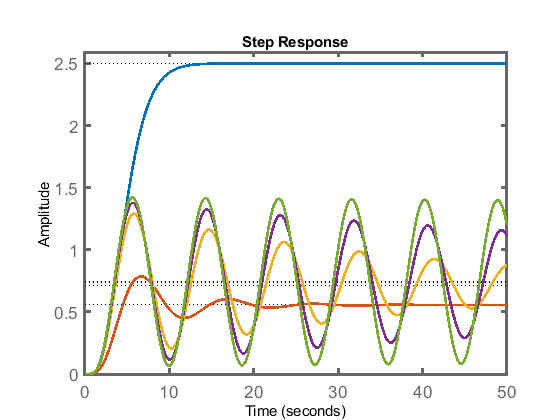

% Graphisch / Graphically
figure(1)
step(PT5); hold on;
step(feedback(0.5*PT5,1),50)
step(feedback(1*PT5,1),50)
step(feedback(1.1*PT5,1),50)
step(feedback(1.15*PT5,1),50)
h=gca; h.LineWidth = 2; h.FontSize =13; h.YLim(2) = 2.6;
lines = findobj(gcf,'Type','Line'); set(lines,'Linewidth',2);

KPkrit =1.15;

% Oder genau via Bisection / or via Bisection algorithm:
Klow = 0.1; %sicher stabil / lower bound for search, for sure stable
Kup = 10; % sicher instabil / upper bound for search, for sure unstable

while Kup-Klow >0.01
   Kn = (Kup+Klow)/2;
   
   if isstable(feedback(Kn*PT5,1))
       Klow=Kn;
   else
       Kup=Kn;
   end
    
end
KPkrit = Kn

KPkrit = 1.1538

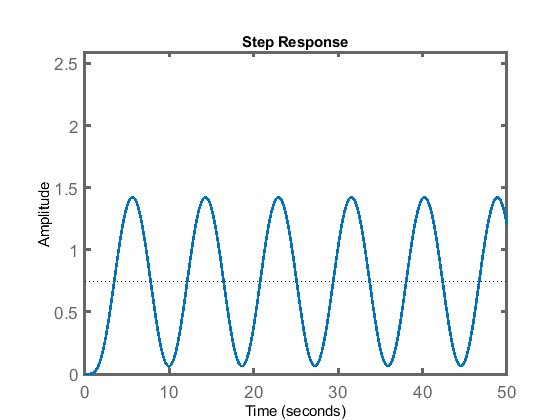

figure(2)
step(feedback(KPkrit*PT5,1),50)
h=gca; h.LineWidth = 2; h.FontSize =13; h.YLim(2) = 2.6;
lines = findobj(gcf,'Type','Line'); set(lines,'Linewidth',2);

## Berechnung / Calculation $T_{krit}$

Graphisch aus Sprunganwort oder berechnen aus Sprungantwort:

Graphically from step-response or calculation from step-response:

% aus  Plot gemessen, ca:
% measured from plot:
Tkrit = 8.5;

[y,t] = step(feedback(1.15*PT5,1),50);

% Finde Nulldurchgaenge des Sinus -> dazu gesamte Antwort um Mittlewert verschieben, signum berechnen und 
% die um einen Zeitschritt verschobene Antwort abziehen

% Search for sin(y) -> to do so, the sine wave is shifted arounf x axis using the mean value; then cacl. sign of function
% and  look for sign changes.
iN = sign(y-mean(y))-sign(circshift(y-mean(y),1));

% nur Vorzeichenwechsel von positiv auf negativ interessant (sonst nur halbe Periode)
% only sign changes from positiv to negative are interesting (otherwise only a half-period)
N = find(iN>0);

% Periode bestimmen durch Subtraktion von Zeit des Nulldurchgangs minus Zeit vom Nulldurchgang davor:
t_2 = circshift(t(N),1);
Tv = t(N(2:end)) - t_2(2:end);

% Periodendauer Mittlen
Tkrit = mean(Tv)

Tkrit = 8.6562

## Bestimmung der Regler / Determine Controller:

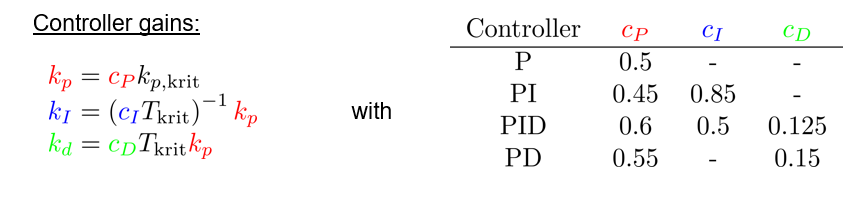

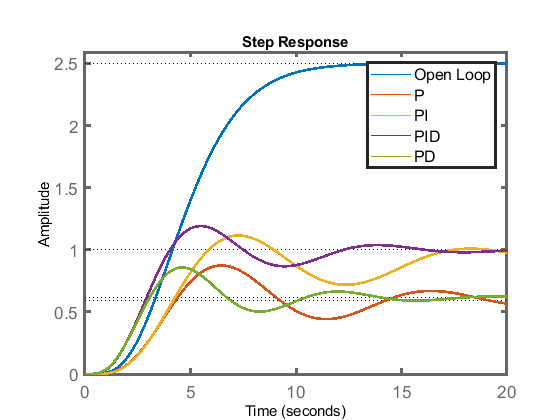

P = 0.5*KPkrit;

PI = 0.45*KPkrit + (0.85*Tkrit)^-1*0.45*KPkrit/s;

PID = 0.6*KPkrit + (0.5*Tkrit)^-1*0.6*KPkrit/s + 0.125*Tkrit*0.6*KPkrit*s;

PD = 0.55*KPkrit +  0.15*Tkrit*0.55*KPkrit*s;


figure(3); 
step(PT5,20);hold on;
step(feedback(P*PT5,1),20);
step(feedback(PI*PT5,1),20)
step(feedback(PID*PT5,1),20)
step(feedback(PD*PT5,1),20)
h=gca; h.LineWidth = 2; h.FontSize =13; h.YLim(2) = 2.6;
lines = findobj(gcf,'Type','Line'); set(lines,'Linewidth',2);
legend('Open Loop','P','PI','PID','PD')

# Via PT1 Näherung (Methode 2) / Variant 2 - via PT1 Approximation

## Bestimmen von $K$, $T_{\text{tot}}$ und $T_{\text{PT}_1}$

## Determine  $K$, $T_{\text{tot}}$ and $T_{\text{PT}_1}$

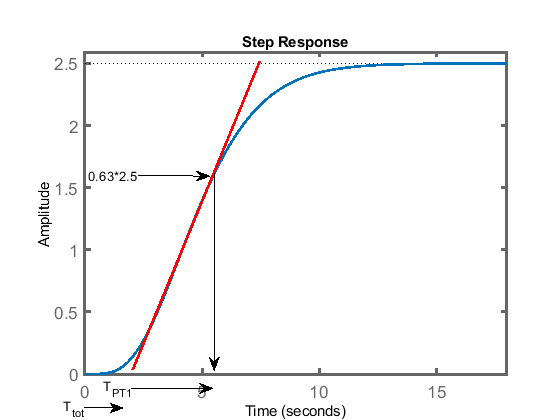

% aus Plot rausgemessen ca. / graphically from plot:
Ttot = 2.1;
K = 2.5;
TPT1 = 3.5;

figure(10)
step(PT5); hold on;
h=gca; h.LineWidth = 2; h.FontSize =13; h.YLim(2) = 2.6;
lines = findobj(gcf,'Type','Line'); set(lines,'Linewidth',2);

annotation('arrow',[0.3825 0.3825],[0.5867 0.1181])
annotation('textarrow',[0.2471 0.3743],[0.5824 0.5805],'String','0.63*2.5')

annotation('line',[0.4639 0.2368],[0.8543 0.119],'Color','red','Linewidth',2)
annotation('textarrow',[0.235 0.38],[0.07524 0.07524],'String','T_{PT1}')
annotation('textarrow',[0.1496 0.2196],[0.02857 0.02857],'String','T_{tot}')

%% Oder BERECHNEN aus Sprungantwort: / or compute from step response;
K = dcgain(PT5);
[y,t] = step(PT5,50);

% Finden von Antwort größer als 25% bzw 50% zu Näherung der Tangente, 90% für Plotten der Tangente, un 63% für PT1 Zeitkonstante
% Find the response >25% and 50% for tangend approximation, 90% for plotting the tangend, and 63% for for the time constant
iN25 = find(y>0.25*K);
iN50 = find(y>0.5*K);
iN90 = find(y>0.90*K);
iN63 = find(y>0.63*K);

% Extrapolation der Tangente  für t=0 und t(y=90%) für das Plotten
% Extrapolation of tangent for t=0 and t(y=90%) for a nice plot:
y_Tang1 = interp1([t(iN25(1)) t(iN50(1))],[y(iN25(1)) y(iN50(1))],0,'linear','extrap');
y_Tang2 = interp1([t(iN25(1)) t(iN50(1))],[y(iN25(1)) y(iN50(1))],t(iN90(1)),'linear','extrap');

% Extrapolation der Tangente für y=0 zur Bestimmung der Totzeit
% Extrapolation of tangent for y=0 to determine time delay
Ttot= interp1([y(iN25(1)) y(iN50(1))],[t(iN25(1)) t(iN50(1))],0,'linear','extrap')

Ttot = 2.0547

% Zeitkonstante bei 63% der Sprungantwort minus Totzeit
% Time constant via 63% rule:
TPT1 = t(iN63(1)) - Ttot

TPT1 = 3.4453

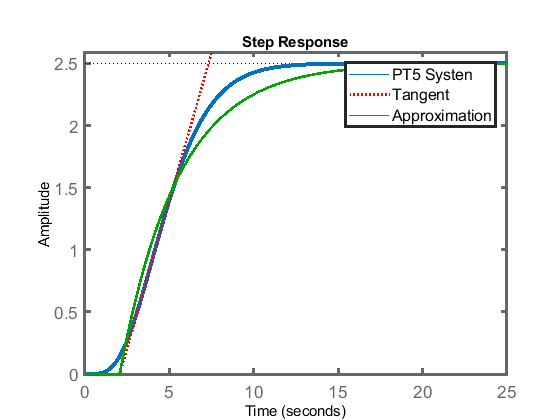

figure(4)
step(PT5); hold on;
plot([Ttot t(iN90(1))],[0 y_Tang2],'r:')

GPT1 = K/(TPT1*s + 1);
GPT1.Inputdelay = Ttot;
step(GPT1,'g');
h=gca; h.LineWidth = 2; h.FontSize =13; h.YLim(2) = 2.6;
h.Children(1).Children(2).LineWidth =2;
h.Children(3).Children(2).LineWidth =3;
h.Children(2).LineWidth =2;
legend('PT5 Systen','Tangent','Approximation')

## Bestimmung der Regler / Detrmine controller gains:

## 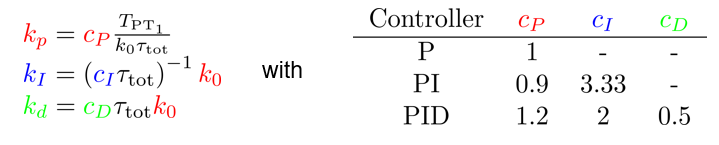

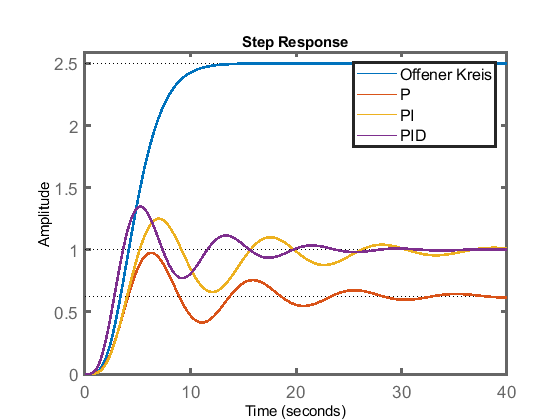

P =  TPT1/(K*Ttot);

PI = 0.9*TPT1/(K*Ttot) + (3.33*Ttot)^-1*0.9*TPT1/(K*Ttot)/s;

PID = 1.2*TPT1/(K*Ttot) + (2*Ttot)^-1*1.2*TPT1/(K*Ttot)/s  +  0.5* Ttot *1.2*TPT1/(K*Ttot)*s/(0.1*s+1);


figure(5); 
step(PT5,40);hold on
step(feedback(P*PT5,1),40)
step(feedback(PI*PT5,1),40)
step(feedback(PID*PT5,1),40)
h=gca; h.LineWidth = 2; h.FontSize =13; h.YLim(2) = 2.6;
lines = findobj(gcf,'Type','Line'); set(lines,'Linewidth',2);
legend('Offener Kreis','P','PI','PID')

## Bsp aus Wiki> hier ist es an sich egal, das Verhältnis von Tg/Tu ist groesser als 2 und daher ist das System gut regelbar.

Oben ist es eben mit einem Wert von 2 an der grenze und dabei ergbt sich dann ein zu grosses gain. Daher ist meiner meinungnach sauber ein PT1Tt anzupassen via 63% Sprungantwort und dann nach bei Ziegler Nichols die Werte ausgehend vom PT1 yu bestimmen. Ist das Verhaeltnis groesser 2 gilt die Naeherung ueber T1 ~ T besser.

G = 1/(2.4*s+1)/(1.2*s+1)/(0.6*s+1)/(.1*s+1);
dt = 0;
G.InputDelay =dt

G =
 
                        1
  ---------------------------------------------
  0.1728 s^4 + 2.232 s^3 + 5.46 s^2 + 4.3 s + 1
 
Continuous-time transfer function.





[y,t] = step(G);
K = dcgain(G);
[y,t] = step(G,50);

% Finden von Antwort größer als 25% bzw 50% zu Näherung der Tangente, 90%
% für Plotten der Tangente, un 63% für PT1 Zeitkonstante
iN25 = find(y>0.25*K);
iN50 = find(y>0.5*K);
iN90 = find(y>0.90*K);
iN63 = find(y>0.63*K);

% Extrapolation der Tangente  für t=0 und t(y=90%) für das Plotten
y_Tang1 = interp1([t(iN25(1)) t(iN50(1))],[y(iN25(1)) y(iN50(1))],0,'linear','extrap');
y_Tang2 = interp1([t(iN25(1)) t(iN50(1))],[y(iN25(1)) y(iN50(1))],t(iN90(1)),'linear','extrap');

% Extrapolation der Tangente für y=0 zur Bestimmung der Totzeit
Ttot= interp1([y(iN25(1)) y(iN50(1))],[t(iN25(1)) t(iN50(1))],0,'linear','extrap')

Ttot = 0.9662

TPT1 = t(iN63(1)) - Ttot

TPT1 = 3.6194

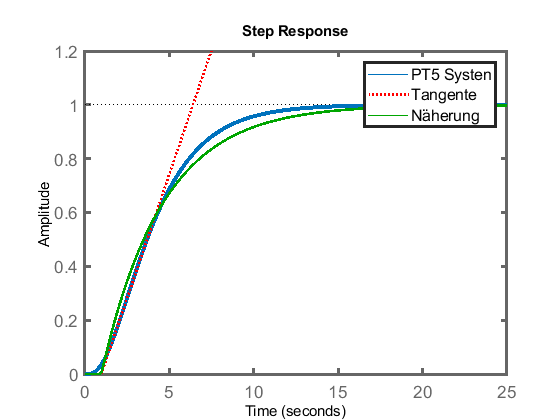


figure(6)
step(G); hold on;
plot([Ttot t(iN90(1))],[0 y_Tang2],'r:')

GPT1 = K/(TPT1*s + 1);
GPT1.Inputdelay = Ttot;
step(GPT1,'g');
h=gca; h.LineWidth = 2; h.FontSize =13; h.YLim(2) = 1.2;
h.Children(1).Children(2).LineWidth =2;
h.Children(3).Children(2).LineWidth =3;
h.Children(2).LineWidth =2;
legend('PT5 Systen','Tangente','Näherung')

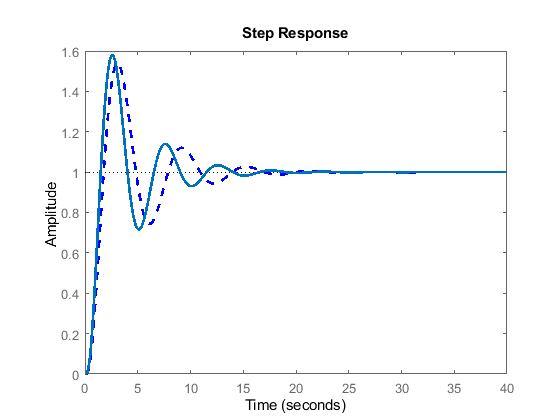

figure(7)
PID = 1.2*TPT1/(K*Ttot) + (2*Ttot)^-1*1.2*TPT1/(K*Ttot)/s  +  0.5* Ttot *1.2*TPT1/(K*Ttot)*s/(0.1*s+1);

step(feedback(PID*G,1),40,'--'); hold on;

Ttot=1.030072+dt; TPT1=5.183502; K=1;

PID = 1.2*TPT1/(K*Ttot) + (2*Ttot)^-1*1.2*TPT1/(K*Ttot)/s  +  0.5* Ttot *1.2*TPT1/(K*Ttot)*s/(0.1*s+1);
% 
 step(feedback(PID*G,1),40)
 lines = findobj(gcf,'Type','Line'); set(lines,'Linewidth',2);